# Solucion taller 1 robotica movil Juan Pablo Zuluaga C

## **Pregunta 1:**

Por favor demostrar que el modelo cinemático se puede expresar por las ecuaciones: 

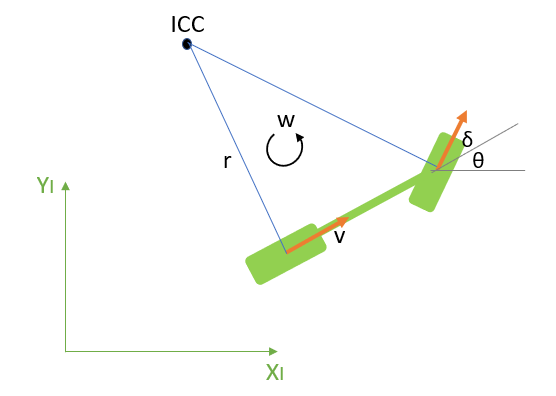


$$\begin{array}{l}
{\dot{x} }^I =v_x^R \;\mathrm{cos}\;\theta \\
{\dot{y} }^I =v_x^R \;\mathrm{sin}\;\theta \\
{\theta^˙ }^I =\;\frac{v_x^R \;\mathrm{tan}\left(\delta \right)}{L}
\end{array}$$
          

### Solución 


$${\left\lbrack \begin{array}{c}
{\dot{x} }^I \\
{\dot{y} }^I \\
{\theta^˙ }^I 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \theta  & -\sin \theta  & 0\\
\sin \theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\textrm{Vx}\\
0\\
\omega 
\end{array}\right\rbrack }^{\prime }$$



$$\left\lbrack \begin{array}{c}
{\dot{x} }^I \\
{\dot{y} }^I \\
{\theta^˙ }^I 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{VxCos}\theta \\
\textrm{VxSin}\theta \\
\omega 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{VxCos}\theta \\
\textrm{VxSin}\theta \\
?
\end{array}\right\rbrack$$



$$\omega =\frac{\textrm{Vx}}{r}\Longrightarrow \tan \left(\delta \right)=\frac{L}{r}\Longrightarrow r=\frac{L}{\tan \left(\delta \right)}$$



$$\omega =\textrm{Vx}*\frac{\tan \left(\delta \right)}{L}$$


Por lo tanto finalmente se obtiene que : 


$$\left\lbrack \begin{array}{c}
{\dot{x} }^I \\
{\dot{y} }^I \\
{\theta^˙ }^I 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{VxCos}\theta \\
\textrm{VxSin}\theta \\
\omega 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{VxCos}\theta \\
\textrm{VxSin}\theta \\
\frac{\textrm{Vx}*\tan \left(\delta \right)}{L}
\end{array}\right\rbrack$$


## **Pregunta 2:**

Por favor comparar esta ecuación con la ecuación  (5.5) de la Clase 2 (lecture_02.mlx) del robot diferencial. Aunque son similares, hay una diferencia clara desde el punto de vista matemático. Esta diferencia como se ve reflejada en la realidad al controlar un carro?

### **Solución**

La diferencia entre estos dos modelos se puede observar en el angulo, mientras que en el modelo diferencial depende de la velocidad angular en el modelo bicicleta es una ecuacion con mas componentes. Esto al controlar un carro en la realidad se podria observar que este puede realizar cambios de direccion de una manera suave y de esta manera se evidencia una mejor experiencia para el usuario.

## **Pregunta 3**

Crear una clase en MATLAB llamada *BicycleModel *e implementar los siguientes métodos:

- calcForwardKinematics

- calcInverseKinematics

### **Solución**

robot = BicycleModel(0.2,0.5)

robot =   BicycleModel with properties:

    WheelRadius: 0.2000
      WheelBase: 0.5000


[r_xi2] = robot.calcForwardKinematics(3,0.2)

r_xi2 =     0.6000
         0
    0.2433


[wr2,delta2] = robot.calcInverseKinematics(r_xi2)

wr2 = 3.0000

delta2 = 0.2000

En el caso de que Vx sea 0 el delta es desconocido, no es posible calcular

robot = BicycleModel(0.2,0.5)

robot =   BicycleModel with properties:

    WheelRadius: 0.2000
      WheelBase: 0.5000


[r_xi2] = robot.calcForwardKinematics(0,0.2)

r_xi2 =      0
     0
     0


[wr2,delta2] = robot.calcInverseKinematics(r_xi2)

wr2 = 0

delta2 = 0

## **Pregunta 4: **

Implementar en Simulink un subsistema del modelo bicicleta del carro donde las entradas son 

- velocidad angular de las llantas traseras 

- ángulo del timón 

Al simular el modelo se deben ver la trajectoria en el espacio del robot.

### **Solución**

open('bicycleModel.slx')

## **Pregunta 5:**

Según lo que han visto en este taller,  la tracción diferencial parece más fácil que controlar que la tracción del carro. Si es por eso, por qué los carros que vemos en la calle no tienen tracción diferencial y la tracción diferencial solo la vemos en robots?

### **Solución**

No es viable construir un carro con traccion diferencial ya que el usuario necesitaria controlar cada rueda y es mas dificil de manejar, mientras que en el que se implementó mediante el timon es mas facil controlarlo para el usuario y mucho mas viable 